# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

## Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- `ex1.m, ex1_multi.m` - MATLAB scripts that step you through the exercise. (Not needed if using `ex1.mlx.)`

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variable

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

## Setting up your environment

The commands below to clear your workspace of existing variables, display your current directory, and list the files in your current directory. To run the code inside of a MATLAB Live Script section:

- Click into the section to make it active. A blue bar will appear on the left.

- Click either the **Run Section (CTRL+ENTER)** or **Run and Advance (CTRL+SHIFT+ENTER) **buttons in the **Live Editor** tab above. Alternatively, you can click on the blue bar.

In general you will only need to run the commands inside the Live Scripts and not in the command window, except when submitting the exercise files. After running this section, you should see all of the files below listed. 

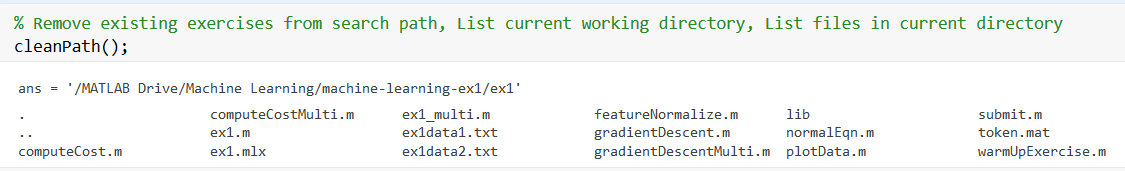

If they are not, change your Current Folder to the **ex1** exercise folder (right-click the ex1 folder and select 'Open'). 

% Clear existing variables
clear;
% Remove existing exercises from search path, list current working directory, and list files in current directory
cleanPath();

ans = '/MATLAB Drive'


.                     ..                    .session              Published             Shared                machine-learning-ex1  token.mat             



Note that:

- You may have to reset your Current Folder to the exercise folder after logging out of MATLAB Online.

- The **Run All** and **Run to End** buttons are not recommended for use in these exercises. 

- Executing the Live Script from the command line is also not recommended. 

- You may have to rerun one or more sections after adressing errors in your code or after clearing the workspace variables.

# 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

A =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


You should see output similar to the following:

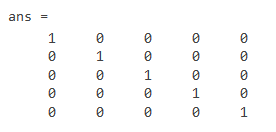

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

## 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

# 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

## 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

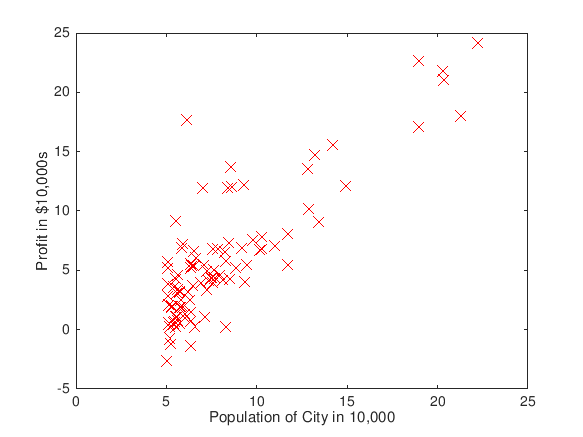

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

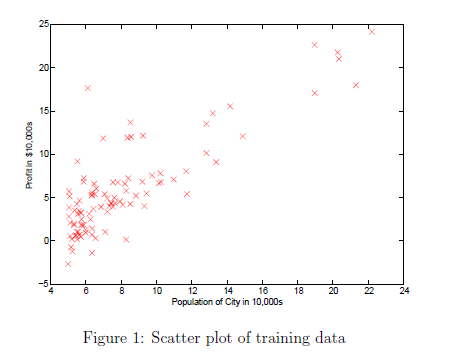

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

# 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

## 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^{m} {\left(h_{\theta \text{ }} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \text{ }$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\text{ }1}{m}\sum_{i=1}^{m} \text{ }\left(h_{\theta \text{ }} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \text{       }\left(\mathrm{simultaneously}\text{ }\mathrm{update}\text{ }\theta_{j\text{ }} \text{ }\mathrm{for}\text{ }\mathrm{all}\text{ }j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

## 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X) % number of training examples
X = [ones(m, 1), data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

## 2.2.3 Computing the cost $\mathbf{J}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07.

% Compute and display initial cost
computeCost(X, y, theta)

ans = 32.0727

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

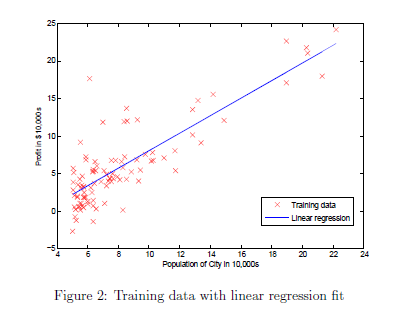    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

theta =     0.0584
    0.6533


theta =     0.0629
    0.7700


theta =     0.0578
    0.7913


theta =     0.0511
    0.7957


theta =     0.0440
    0.7971


theta =     0.0369
    0.7979


theta =     0.0298
    0.7987


theta =     0.0228
    0.7994


theta =     0.0157
    0.8001


theta =     0.0086
    0.8008


theta =     0.0016
    0.8015


theta =    -0.0054
    0.8022


theta =    -0.0124
    0.8029


theta =    -0.0194
    0.8036


theta =    -0.0264
    0.8043


theta =    -0.0334
    0.8050


theta =    -0.0404
    0.8057


theta =    -0.0473
    0.8064


theta =    -0.0542
    0.8071


theta =    -0.0612
    0.8078


theta =    -0.0681
    0.8085


theta =    -0.0750
    0.8092


theta =    -0.0819
    0.8099


theta =    -0.0887
    0.8106


theta =    -0.0956
    0.8113


theta =    -0.1025
    0.8120


theta =    -0.1093
    0.8126


theta =    -0.1161
    0.8133


theta =    -0.1229
    0.8140


theta =    -0.1297
    0.8147


theta =    -0.1365
    0.8154


theta =    -0.1433
    0.8161


theta =    -0.1501
    0.8167


theta =    -0.1568
    0.8174


theta =    -0.1636
    0.8181


theta =    -0.1703
    0.8188


theta =    -0.1770
    0.8194


theta =    -0.1837
    0.8201


theta =    -0.1904
    0.8208


theta =    -0.1971
    0.8215


theta =    -0.2037
    0.8221


theta =    -0.2104
    0.8228


theta =    -0.2170
    0.8235


theta =    -0.2237
    0.8241


theta =    -0.2303
    0.8248


theta =    -0.2369
    0.8255


theta =    -0.2435
    0.8261


theta =    -0.2501
    0.8268


theta =    -0.2566
    0.8274


theta =    -0.2632
    0.8281


theta =    -0.2698
    0.8288


theta =    -0.2763
    0.8294


theta =    -0.2828
    0.8301


theta =    -0.2893
    0.8307


theta =    -0.2958
    0.8314


theta =    -0.3023
    0.8320


theta =    -0.3088
    0.8327


theta =    -0.3153
    0.8333


theta =    -0.3217
    0.8340


theta =    -0.3282
    0.8346


theta =    -0.3346
    0.8353


theta =    -0.3410
    0.8359


theta =    -0.3474
    0.8366


theta =    -0.3538
    0.8372


theta =    -0.3602
    0.8378


theta =    -0.3666
    0.8385


theta =    -0.3729
    0.8391


theta =    -0.3793
    0.8398


theta =    -0.3856
    0.8404


theta =    -0.3919
    0.8410


theta =    -0.3983
    0.8417


theta =    -0.4046
    0.8423


theta =    -0.4109
    0.8429


theta =    -0.4171
    0.8436


theta =    -0.4234
    0.8442


theta =    -0.4297
    0.8448


theta =    -0.4359
    0.8455


theta =    -0.4422
    0.8461


theta =    -0.4484
    0.8467


theta =    -0.4546
    0.8473


theta =    -0.4608
    0.8480


theta =    -0.4670
    0.8486


theta =    -0.4732
    0.8492


theta =    -0.4793
    0.8498


theta =    -0.4855
    0.8504


theta =    -0.4916
    0.8511


theta =    -0.4978
    0.8517


theta =    -0.5039
    0.8523


theta =    -0.5100
    0.8529


theta =    -0.5161
    0.8535


theta =    -0.5222
    0.8541


theta =    -0.5283
    0.8547


theta =    -0.5344
    0.8553


theta =    -0.5404
    0.8560


theta =    -0.5465
    0.8566


theta =    -0.5525
    0.8572


theta =    -0.5585
    0.8578


theta =    -0.5646
    0.8584


theta =    -0.5706
    0.8590


theta =    -0.5766
    0.8596


theta =    -0.5825
    0.8602


theta =    -0.5885
    0.8608


theta =    -0.5945
    0.8614


theta =    -0.6004
    0.8620


theta =    -0.6064
    0.8626


theta =    -0.6123
    0.8632


theta =    -0.6182
    0.8638


theta =    -0.6241
    0.8644


theta =    -0.6300
    0.8650


theta =    -0.6359
    0.8655


theta =    -0.6418
    0.8661


theta =    -0.6476
    0.8667


theta =    -0.6535
    0.8673


theta =    -0.6593
    0.8679


theta =    -0.6652
    0.8685


theta =    -0.6710
    0.8691


theta =    -0.6768
    0.8697


theta =    -0.6826
    0.8702


theta =    -0.6884
    0.8708


theta =    -0.6942
    0.8714


theta =    -0.7000
    0.8720


theta =    -0.7057
    0.8726


theta =    -0.7115
    0.8731


theta =    -0.7172
    0.8737


theta =    -0.7229
    0.8743


theta =    -0.7287
    0.8749


theta =    -0.7344
    0.8754


theta =    -0.7401
    0.8760


theta =    -0.7458
    0.8766


theta =    -0.7514
    0.8772


theta =    -0.7571
    0.8777


theta =    -0.7628
    0.8783


theta =    -0.7684
    0.8789


theta =    -0.7740
    0.8794


theta =    -0.7797
    0.8800


theta =    -0.7853
    0.8806


theta =    -0.7909
    0.8811


theta =    -0.7965
    0.8817


theta =    -0.8021
    0.8822


theta =    -0.8077
    0.8828


theta =    -0.8132
    0.8834


theta =    -0.8188
    0.8839


theta =    -0.8243
    0.8845


theta =    -0.8299
    0.8850


theta =    -0.8354
    0.8856


theta =    -0.8409
    0.8861


theta =    -0.8464
    0.8867


theta =    -0.8519
    0.8872


theta =    -0.8574
    0.8878


theta =    -0.8629
    0.8883


theta =    -0.8683
    0.8889


theta =    -0.8738
    0.8894


theta =    -0.8793
    0.8900


theta =    -0.8847
    0.8905


theta =    -0.8901
    0.8911


theta =    -0.8955
    0.8916


theta =    -0.9009
    0.8922


theta =    -0.9063
    0.8927


theta =    -0.9117
    0.8933


theta =    -0.9171
    0.8938


theta =    -0.9225
    0.8943


theta =    -0.9278
    0.8949


theta =    -0.9332
    0.8954


theta =    -0.9385
    0.8959


theta =    -0.9439
    0.8965


theta =    -0.9492
    0.8970


theta =    -0.9545
    0.8975


theta =    -0.9598
    0.8981


theta =    -0.9651
    0.8986


theta =    -0.9704
    0.8991


theta =    -0.9756
    0.8997


theta =    -0.9809
    0.9002


theta =    -0.9862
    0.9007


theta =    -0.9914
    0.9013


theta =    -0.9966
    0.9018


theta =    -1.0019
    0.9023


theta =    -1.0071
    0.9028


theta =    -1.0123
    0.9034


theta =    -1.0175
    0.9039


theta =    -1.0227
    0.9044


theta =    -1.0279
    0.9049


theta =    -1.0330
    0.9054


theta =    -1.0382
    0.9060


theta =    -1.0433
    0.9065


theta =    -1.0485
    0.9070


theta =    -1.0536
    0.9075


theta =    -1.0587
    0.9080


theta =    -1.0638
    0.9085


theta =    -1.0690
    0.9090


theta =    -1.0740
    0.9096


theta =    -1.0791
    0.9101


theta =    -1.0842
    0.9106


theta =    -1.0893
    0.9111


theta =    -1.0943
    0.9116


theta =    -1.0994
    0.9121


theta =    -1.1044
    0.9126


theta =    -1.1095
    0.9131


theta =    -1.1145
    0.9136


theta =    -1.1195
    0.9141


theta =    -1.1245
    0.9146


theta =    -1.1295
    0.9151


theta =    -1.1345
    0.9156


theta =    -1.1395
    0.9161


theta =    -1.1444
    0.9166


theta =    -1.1494
    0.9171


theta =    -1.1543
    0.9176


theta =    -1.1593
    0.9181


theta =    -1.1642
    0.9186


theta =    -1.1691
    0.9191


theta =    -1.1741
    0.9196


theta =    -1.1790
    0.9201


theta =    -1.1839
    0.9206


theta =    -1.1887
    0.9211


theta =    -1.1936
    0.9216


theta =    -1.1985
    0.9221


theta =    -1.2034
    0.9226


theta =    -1.2082
    0.9230


theta =    -1.2131
    0.9235


theta =    -1.2179
    0.9240


theta =    -1.2227
    0.9245


theta =    -1.2275
    0.9250


theta =    -1.2323
    0.9255


theta =    -1.2371
    0.9259


theta =    -1.2419
    0.9264


theta =    -1.2467
    0.9269


theta =    -1.2515
    0.9274


theta =    -1.2563
    0.9279


theta =    -1.2610
    0.9283


theta =    -1.2658
    0.9288


theta =    -1.2705
    0.9293


theta =    -1.2752
    0.9298


theta =    -1.2800
    0.9302


theta =    -1.2847
    0.9307


theta =    -1.2894
    0.9312


theta =    -1.2941
    0.9317


theta =    -1.2988
    0.9321


theta =    -1.3035
    0.9326


theta =    -1.3081
    0.9331


theta =    -1.3128
    0.9335


theta =    -1.3175
    0.9340


theta =    -1.3221
    0.9345


theta =    -1.3267
    0.9349


theta =    -1.3314
    0.9354


theta =    -1.3360
    0.9359


theta =    -1.3406
    0.9363


theta =    -1.3452
    0.9368


theta =    -1.3498
    0.9373


theta =    -1.3544
    0.9377


theta =    -1.3590
    0.9382


theta =    -1.3636
    0.9386


theta =    -1.3681
    0.9391


theta =    -1.3727
    0.9396


theta =    -1.3772
    0.9400


theta =    -1.3818
    0.9405


theta =    -1.3863
    0.9409


theta =    -1.3908
    0.9414


theta =    -1.3953
    0.9418


theta =    -1.3998
    0.9423


theta =    -1.4043
    0.9427


theta =    -1.4088
    0.9432


theta =    -1.4133
    0.9436


theta =    -1.4178
    0.9441


theta =    -1.4223
    0.9445


theta =    -1.4267
    0.9450


theta =    -1.4312
    0.9454


theta =    -1.4356
    0.9459


theta =    -1.4400
    0.9463


theta =    -1.4445
    0.9468


theta =    -1.4489
    0.9472


theta =    -1.4533
    0.9477


theta =    -1.4577
    0.9481


theta =    -1.4621
    0.9485


theta =    -1.4665
    0.9490


theta =    -1.4709
    0.9494


theta =    -1.4752
    0.9499


theta =    -1.4796
    0.9503


theta =    -1.4840
    0.9507


theta =    -1.4883
    0.9512


theta =    -1.4926
    0.9516


theta =    -1.4970
    0.9520


theta =    -1.5013
    0.9525


theta =    -1.5056
    0.9529


theta =    -1.5099
    0.9533


theta =    -1.5142
    0.9538


theta =    -1.5185
    0.9542


theta =    -1.5228
    0.9546


theta =    -1.5271
    0.9551


theta =    -1.5313
    0.9555


theta =    -1.5356
    0.9559


theta =    -1.5399
    0.9564


theta =    -1.5441
    0.9568


theta =    -1.5484
    0.9572


theta =    -1.5526
    0.9576


theta =    -1.5568
    0.9581


theta =    -1.5610
    0.9585


theta =    -1.5652
    0.9589


theta =    -1.5694
    0.9593


theta =    -1.5736
    0.9597


theta =    -1.5778
    0.9602


theta =    -1.5820
    0.9606


theta =    -1.5862
    0.9610


theta =    -1.5903
    0.9614


theta =    -1.5945
    0.9618


theta =    -1.5986
    0.9623


theta =    -1.6028
    0.9627


theta =    -1.6069
    0.9631


theta =    -1.6110
    0.9635


theta =    -1.6151
    0.9639


theta =    -1.6193
    0.9643


theta =    -1.6234
    0.9647


theta =    -1.6275
    0.9652


theta =    -1.6315
    0.9656


theta =    -1.6356
    0.9660


theta =    -1.6397
    0.9664


theta =    -1.6438
    0.9668


theta =    -1.6478
    0.9672


theta =    -1.6519
    0.9676


theta =    -1.6559
    0.9680


theta =    -1.6600
    0.9684


theta =    -1.6640
    0.9688


theta =    -1.6680
    0.9692


theta =    -1.6720
    0.9696


theta =    -1.6760
    0.9700


theta =    -1.6800
    0.9704


theta =    -1.6840
    0.9708


theta =    -1.6880
    0.9712


theta =    -1.6920
    0.9716


theta =    -1.6960
    0.9720


theta =    -1.6999
    0.9724


theta =    -1.7039
    0.9728


theta =    -1.7079
    0.9732


theta =    -1.7118
    0.9736


theta =    -1.7157
    0.9740


theta =    -1.7197
    0.9744


theta =    -1.7236
    0.9748


theta =    -1.7275
    0.9752


theta =    -1.7314
    0.9756


theta =    -1.7353
    0.9760


theta =    -1.7392
    0.9764


theta =    -1.7431
    0.9768


theta =    -1.7470
    0.9772


theta =    -1.7508
    0.9776


theta =    -1.7547
    0.9779


theta =    -1.7586
    0.9783


theta =    -1.7624
    0.9787


theta =    -1.7663
    0.9791


theta =    -1.7701
    0.9795


theta =    -1.7739
    0.9799


theta =    -1.7778
    0.9803


theta =    -1.7816
    0.9806


theta =    -1.7854
    0.9810


theta =    -1.7892
    0.9814


theta =    -1.7930
    0.9818


theta =    -1.7968
    0.9822


theta =    -1.8006
    0.9825


theta =    -1.8043
    0.9829


theta =    -1.8081
    0.9833


theta =    -1.8119
    0.9837


theta =    -1.8156
    0.9841


theta =    -1.8194
    0.9844


theta =    -1.8231
    0.9848


theta =    -1.8269
    0.9852


theta =    -1.8306
    0.9856


theta =    -1.8343
    0.9859


theta =    -1.8380
    0.9863


theta =    -1.8417
    0.9867


theta =    -1.8454
    0.9871


theta =    -1.8491
    0.9874


theta =    -1.8528
    0.9878


theta =    -1.8565
    0.9882


theta =    -1.8602
    0.9885


theta =    -1.8639
    0.9889


theta =    -1.8675
    0.9893


theta =    -1.8712
    0.9896


theta =    -1.8748
    0.9900


theta =    -1.8785
    0.9904


theta =    -1.8821
    0.9907


theta =    -1.8857
    0.9911


theta =    -1.8894
    0.9915


theta =    -1.8930
    0.9918


theta =    -1.8966
    0.9922


theta =    -1.9002
    0.9926


theta =    -1.9038
    0.9929


theta =    -1.9074
    0.9933


theta =    -1.9110
    0.9936


theta =    -1.9145
    0.9940


theta =    -1.9181
    0.9944


theta =    -1.9217
    0.9947


theta =    -1.9252
    0.9951


theta =    -1.9288
    0.9954


theta =    -1.9323
    0.9958


theta =    -1.9359
    0.9961


theta =    -1.9394
    0.9965


theta =    -1.9429
    0.9968


theta =    -1.9465
    0.9972


theta =    -1.9500
    0.9976


theta =    -1.9535
    0.9979


theta =    -1.9570
    0.9983


theta =    -1.9605
    0.9986


theta =    -1.9640
    0.9990


theta =    -1.9674
    0.9993


theta =    -1.9709
    0.9997


theta =    -1.9744
    1.0000


theta =    -1.9778
    1.0004


theta =    -1.9813
    1.0007


theta =    -1.9848
    1.0011


theta =    -1.9882
    1.0014


theta =    -1.9916
    1.0017


theta =    -1.9951
    1.0021


theta =    -1.9985
    1.0024


theta =    -2.0019
    1.0028


theta =    -2.0053
    1.0031


theta =    -2.0087
    1.0035


theta =    -2.0121
    1.0038


theta =    -2.0155
    1.0041


theta =    -2.0189
    1.0045


theta =    -2.0223
    1.0048


theta =    -2.0257
    1.0052


theta =    -2.0291
    1.0055


theta =    -2.0324
    1.0058


theta =    -2.0358
    1.0062


theta =    -2.0391
    1.0065


theta =    -2.0425
    1.0068


theta =    -2.0458
    1.0072


theta =    -2.0492
    1.0075


theta =    -2.0525
    1.0079


theta =    -2.0558
    1.0082


theta =    -2.0591
    1.0085


theta =    -2.0624
    1.0089


theta =    -2.0657
    1.0092


theta =    -2.0690
    1.0095


theta =    -2.0723
    1.0098


theta =    -2.0756
    1.0102


theta =    -2.0789
    1.0105


theta =    -2.0822
    1.0108


theta =    -2.0854
    1.0112


theta =    -2.0887
    1.0115


theta =    -2.0920
    1.0118


theta =    -2.0952
    1.0121


theta =    -2.0985
    1.0125


theta =    -2.1017
    1.0128


theta =    -2.1049
    1.0131


theta =    -2.1082
    1.0134


theta =    -2.1114
    1.0138


theta =    -2.1146
    1.0141


theta =    -2.1178
    1.0144


theta =    -2.1210
    1.0147


theta =    -2.1242
    1.0151


theta =    -2.1274
    1.0154


theta =    -2.1306
    1.0157


theta =    -2.1338
    1.0160


theta =    -2.1370
    1.0163


theta =    -2.1401
    1.0167


theta =    -2.1433
    1.0170


theta =    -2.1465
    1.0173


theta =    -2.1496
    1.0176


theta =    -2.1528
    1.0179


theta =    -2.1559
    1.0182


theta =    -2.1590
    1.0186


theta =    -2.1622
    1.0189


theta =    -2.1653
    1.0192


theta =    -2.1684
    1.0195


theta =    -2.1715
    1.0198


theta =    -2.1746
    1.0201


theta =    -2.1777
    1.0204


theta =    -2.1808
    1.0207


theta =    -2.1839
    1.0211


theta =    -2.1870
    1.0214


theta =    -2.1901
    1.0217


theta =    -2.1932
    1.0220


theta =    -2.1962
    1.0223


theta =    -2.1993
    1.0226


theta =    -2.2024
    1.0229


theta =    -2.2054
    1.0232


theta =    -2.2085
    1.0235


theta =    -2.2115
    1.0238


theta =    -2.2145
    1.0241


theta =    -2.2176
    1.0244


theta =    -2.2206
    1.0247


theta =    -2.2236
    1.0250


theta =    -2.2266
    1.0253


theta =    -2.2296
    1.0257


theta =    -2.2326
    1.0260


theta =    -2.2356
    1.0263


theta =    -2.2386
    1.0266


theta =    -2.2416
    1.0269


theta =    -2.2446
    1.0272


theta =    -2.2476
    1.0275


theta =    -2.2505
    1.0278


theta =    -2.2535
    1.0280


theta =    -2.2565
    1.0283


theta =    -2.2594
    1.0286


theta =    -2.2624
    1.0289


theta =    -2.2653
    1.0292


theta =    -2.2683
    1.0295


theta =    -2.2712
    1.0298


theta =    -2.2741
    1.0301


theta =    -2.2770
    1.0304


theta =    -2.2800
    1.0307


theta =    -2.2829
    1.0310


theta =    -2.2858
    1.0313


theta =    -2.2887
    1.0316


theta =    -2.2916
    1.0319


theta =    -2.2945
    1.0322


theta =    -2.2974
    1.0325


theta =    -2.3002
    1.0327


theta =    -2.3031
    1.0330


theta =    -2.3060
    1.0333


theta =    -2.3088
    1.0336


theta =    -2.3117
    1.0339


theta =    -2.3146
    1.0342


theta =    -2.3174
    1.0345


theta =    -2.3203
    1.0348


theta =    -2.3231
    1.0350


theta =    -2.3259
    1.0353


theta =    -2.3288
    1.0356


theta =    -2.3316
    1.0359


theta =    -2.3344
    1.0362


theta =    -2.3372
    1.0365


theta =    -2.3400
    1.0367


theta =    -2.3428
    1.0370


theta =    -2.3456
    1.0373


theta =    -2.3484
    1.0376


theta =    -2.3512
    1.0379


theta =    -2.3540
    1.0381


theta =    -2.3568
    1.0384


theta =    -2.3596
    1.0387


theta =    -2.3623
    1.0390


theta =    -2.3651
    1.0393


theta =    -2.3678
    1.0395


theta =    -2.3706
    1.0398


theta =    -2.3734
    1.0401


theta =    -2.3761
    1.0404


theta =    -2.3788
    1.0406


theta =    -2.3816
    1.0409


theta =    -2.3843
    1.0412


theta =    -2.3870
    1.0415


theta =    -2.3897
    1.0417


theta =    -2.3925
    1.0420


theta =    -2.3952
    1.0423


theta =    -2.3979
    1.0426


theta =    -2.4006
    1.0428


theta =    -2.4033
    1.0431


theta =    -2.4060
    1.0434


theta =    -2.4086
    1.0436


theta =    -2.4113
    1.0439


theta =    -2.4140
    1.0442


theta =    -2.4167
    1.0444


theta =    -2.4193
    1.0447


theta =    -2.4220
    1.0450


theta =    -2.4247
    1.0452


theta =    -2.4273
    1.0455


theta =    -2.4300
    1.0458


theta =    -2.4326
    1.0460


theta =    -2.4352
    1.0463


theta =    -2.4379
    1.0466


theta =    -2.4405
    1.0468


theta =    -2.4431
    1.0471


theta =    -2.4457
    1.0474


theta =    -2.4484
    1.0476


theta =    -2.4510
    1.0479


theta =    -2.4536
    1.0481


theta =    -2.4562
    1.0484


theta =    -2.4588
    1.0487


theta =    -2.4614
    1.0489


theta =    -2.4639
    1.0492


theta =    -2.4665
    1.0494


theta =    -2.4691
    1.0497


theta =    -2.4717
    1.0500


theta =    -2.4742
    1.0502


theta =    -2.4768
    1.0505


theta =    -2.4794
    1.0507


theta =    -2.4819
    1.0510


theta =    -2.4845
    1.0513


theta =    -2.4870
    1.0515


theta =    -2.4895
    1.0518


theta =    -2.4921
    1.0520


theta =    -2.4946
    1.0523


theta =    -2.4971
    1.0525


theta =    -2.4997
    1.0528


theta =    -2.5022
    1.0530


theta =    -2.5047
    1.0533


theta =    -2.5072
    1.0535


theta =    -2.5097
    1.0538


theta =    -2.5122
    1.0540


theta =    -2.5147
    1.0543


theta =    -2.5172
    1.0545


theta =    -2.5197
    1.0548


theta =    -2.5221
    1.0550


theta =    -2.5246
    1.0553


theta =    -2.5271
    1.0555


theta =    -2.5296
    1.0558


theta =    -2.5320
    1.0560


theta =    -2.5345
    1.0563


theta =    -2.5369
    1.0565


theta =    -2.5394
    1.0568


theta =    -2.5418
    1.0570


theta =    -2.5443
    1.0573


theta =    -2.5467
    1.0575


theta =    -2.5491
    1.0577


theta =    -2.5516
    1.0580


theta =    -2.5540
    1.0582


theta =    -2.5564
    1.0585


theta =    -2.5588
    1.0587


theta =    -2.5612
    1.0590


theta =    -2.5636
    1.0592


theta =    -2.5660
    1.0594


theta =    -2.5684
    1.0597


theta =    -2.5708
    1.0599


theta =    -2.5732
    1.0602


theta =    -2.5756
    1.0604


theta =    -2.5780
    1.0606


theta =    -2.5803
    1.0609


theta =    -2.5827
    1.0611


theta =    -2.5851
    1.0614


theta =    -2.5874
    1.0616


theta =    -2.5898
    1.0618


theta =    -2.5922
    1.0621


theta =    -2.5945
    1.0623


theta =    -2.5969
    1.0625


theta =    -2.5992
    1.0628


theta =    -2.6015
    1.0630


theta =    -2.6039
    1.0632


theta =    -2.6062
    1.0635


theta =    -2.6085
    1.0637


theta =    -2.6108
    1.0639


theta =    -2.6132
    1.0642


theta =    -2.6155
    1.0644


theta =    -2.6178
    1.0646


theta =    -2.6201
    1.0649


theta =    -2.6224
    1.0651


theta =    -2.6247
    1.0653


theta =    -2.6270
    1.0656


theta =    -2.6293
    1.0658


theta =    -2.6315
    1.0660


theta =    -2.6338
    1.0663


theta =    -2.6361
    1.0665


theta =    -2.6384
    1.0667


theta =    -2.6406
    1.0669


theta =    -2.6429
    1.0672


theta =    -2.6452
    1.0674


theta =    -2.6474
    1.0676


theta =    -2.6497
    1.0678


theta =    -2.6519
    1.0681


theta =    -2.6541
    1.0683


theta =    -2.6564
    1.0685


theta =    -2.6586
    1.0687


theta =    -2.6608
    1.0690


theta =    -2.6631
    1.0692


theta =    -2.6653
    1.0694


theta =    -2.6675
    1.0696


theta =    -2.6697
    1.0699


theta =    -2.6719
    1.0701


theta =    -2.6741
    1.0703


theta =    -2.6763
    1.0705


theta =    -2.6785
    1.0707


theta =    -2.6807
    1.0710


theta =    -2.6829
    1.0712


theta =    -2.6851
    1.0714


theta =    -2.6873
    1.0716


theta =    -2.6895
    1.0718


theta =    -2.6916
    1.0721


theta =    -2.6938
    1.0723


theta =    -2.6960
    1.0725


theta =    -2.6981
    1.0727


theta =    -2.7003
    1.0729


theta =    -2.7025
    1.0732


theta =    -2.7046
    1.0734


theta =    -2.7068
    1.0736


theta =    -2.7089
    1.0738


theta =    -2.7110
    1.0740


theta =    -2.7132
    1.0742


theta =    -2.7153
    1.0744


theta =    -2.7174
    1.0747


theta =    -2.7196
    1.0749


theta =    -2.7217
    1.0751


theta =    -2.7238
    1.0753


theta =    -2.7259
    1.0755


theta =    -2.7280
    1.0757


theta =    -2.7301
    1.0759


theta =    -2.7322
    1.0761


theta =    -2.7343
    1.0764


theta =    -2.7364
    1.0766


theta =    -2.7385
    1.0768


theta =    -2.7406
    1.0770


theta =    -2.7427
    1.0772


theta =    -2.7448
    1.0774


theta =    -2.7468
    1.0776


theta =    -2.7489
    1.0778


theta =    -2.7510
    1.0780


theta =    -2.7530
    1.0782


theta =    -2.7551
    1.0784


theta =    -2.7571
    1.0786


theta =    -2.7592
    1.0789


theta =    -2.7613
    1.0791


theta =    -2.7633
    1.0793


theta =    -2.7653
    1.0795


theta =    -2.7674
    1.0797


theta =    -2.7694
    1.0799


theta =    -2.7714
    1.0801


theta =    -2.7735
    1.0803


theta =    -2.7755
    1.0805


theta =    -2.7775
    1.0807


theta =    -2.7795
    1.0809


theta =    -2.7815
    1.0811


theta =    -2.7835
    1.0813


theta =    -2.7855
    1.0815


theta =    -2.7876
    1.0817


theta =    -2.7895
    1.0819


theta =    -2.7915
    1.0821


theta =    -2.7935
    1.0823


theta =    -2.7955
    1.0825


theta =    -2.7975
    1.0827


theta =    -2.7995
    1.0829


theta =    -2.8015
    1.0831


theta =    -2.8034
    1.0833


theta =    -2.8054
    1.0835


theta =    -2.8074
    1.0837


theta =    -2.8093
    1.0839


theta =    -2.8113
    1.0841


theta =    -2.8132
    1.0843


theta =    -2.8152
    1.0845


theta =    -2.8171
    1.0847


theta =    -2.8191
    1.0849


theta =    -2.8210
    1.0851


theta =    -2.8230
    1.0853


theta =    -2.8249
    1.0855


theta =    -2.8268
    1.0856


theta =    -2.8288
    1.0858


theta =    -2.8307
    1.0860


theta =    -2.8326
    1.0862


theta =    -2.8345
    1.0864


theta =    -2.8364
    1.0866


theta =    -2.8383
    1.0868


theta =    -2.8402
    1.0870


theta =    -2.8421
    1.0872


theta =    -2.8440
    1.0874


theta =    -2.8459
    1.0876


theta =    -2.8478
    1.0878


theta =    -2.8497
    1.0879


theta =    -2.8516
    1.0881


theta =    -2.8535
    1.0883


theta =    -2.8554
    1.0885


theta =    -2.8572
    1.0887


theta =    -2.8591
    1.0889


theta =    -2.8610
    1.0891


theta =    -2.8629
    1.0893


theta =    -2.8647
    1.0895


theta =    -2.8666
    1.0896


theta =    -2.8684
    1.0898


theta =    -2.8703
    1.0900


theta =    -2.8721
    1.0902


theta =    -2.8740
    1.0904


theta =    -2.8758
    1.0906


theta =    -2.8777
    1.0908


theta =    -2.8795
    1.0909


theta =    -2.8813
    1.0911


theta =    -2.8831
    1.0913


theta =    -2.8850
    1.0915


theta =    -2.8868
    1.0917


theta =    -2.8886
    1.0919


theta =    -2.8904
    1.0920


theta =    -2.8922
    1.0922


theta =    -2.8941
    1.0924


theta =    -2.8959
    1.0926


theta =    -2.8977
    1.0928


theta =    -2.8995
    1.0929


theta =    -2.9013
    1.0931


theta =    -2.9030
    1.0933


theta =    -2.9048
    1.0935


theta =    -2.9066
    1.0937


theta =    -2.9084
    1.0938


theta =    -2.9102
    1.0940


theta =    -2.9120
    1.0942


theta =    -2.9137
    1.0944


theta =    -2.9155
    1.0946


theta =    -2.9173
    1.0947


theta =    -2.9190
    1.0949


theta =    -2.9208
    1.0951


theta =    -2.9226
    1.0953


theta =    -2.9243
    1.0954


theta =    -2.9261
    1.0956


theta =    -2.9278
    1.0958


theta =    -2.9296
    1.0960


theta =    -2.9313
    1.0961


theta =    -2.9330
    1.0963


theta =    -2.9348
    1.0965


theta =    -2.9365
    1.0967


theta =    -2.9382
    1.0968


theta =    -2.9400
    1.0970


theta =    -2.9417
    1.0972


theta =    -2.9434
    1.0974


theta =    -2.9451
    1.0975


theta =    -2.9468
    1.0977


theta =    -2.9485
    1.0979


theta =    -2.9502
    1.0980


theta =    -2.9520
    1.0982


theta =    -2.9537
    1.0984


theta =    -2.9554
    1.0986


theta =    -2.9570
    1.0987


theta =    -2.9587
    1.0989


theta =    -2.9604
    1.0991


theta =    -2.9621
    1.0992


theta =    -2.9638
    1.0994


theta =    -2.9655
    1.0996


theta =    -2.9672
    1.0997


theta =    -2.9688
    1.0999


theta =    -2.9705
    1.1001


theta =    -2.9722
    1.1002


theta =    -2.9738
    1.1004


theta =    -2.9755
    1.1006


theta =    -2.9772
    1.1007


theta =    -2.9788
    1.1009


theta =    -2.9805
    1.1011


theta =    -2.9821
    1.1012


theta =    -2.9838
    1.1014


theta =    -2.9854
    1.1016


theta =    -2.9870
    1.1017


theta =    -2.9887
    1.1019


theta =    -2.9903
    1.1021


theta =    -2.9920
    1.1022


theta =    -2.9936
    1.1024


theta =    -2.9952
    1.1026


theta =    -2.9968
    1.1027


theta =    -2.9984
    1.1029


theta =    -3.0001
    1.1030


theta =    -3.0017
    1.1032


theta =    -3.0033
    1.1034


theta =    -3.0049
    1.1035


theta =    -3.0065
    1.1037


theta =    -3.0081
    1.1039


theta =    -3.0097
    1.1040


theta =    -3.0113
    1.1042


theta =    -3.0129
    1.1043


theta =    -3.0145
    1.1045


theta =    -3.0161
    1.1047


theta =    -3.0177
    1.1048


theta =    -3.0193
    1.1050


theta =    -3.0208
    1.1051


theta =    -3.0224
    1.1053


theta =    -3.0240
    1.1055


theta =    -3.0256
    1.1056


theta =    -3.0271
    1.1058


theta =    -3.0287
    1.1059


theta =    -3.0303
    1.1061


theta =    -3.0318
    1.1062


theta =    -3.0334
    1.1064


theta =    -3.0349
    1.1066


theta =    -3.0365
    1.1067


theta =    -3.0380
    1.1069


theta =    -3.0396
    1.1070


theta =    -3.0411
    1.1072


theta =    -3.0427
    1.1073


theta =    -3.0442
    1.1075


theta =    -3.0457
    1.1076


theta =    -3.0473
    1.1078


theta =    -3.0488
    1.1079


theta =    -3.0503
    1.1081


theta =    -3.0518
    1.1083


theta =    -3.0534
    1.1084


theta =    -3.0549
    1.1086


theta =    -3.0564
    1.1087


theta =    -3.0579
    1.1089


theta =    -3.0594
    1.1090


theta =    -3.0609
    1.1092


theta =    -3.0624
    1.1093


theta =    -3.0639
    1.1095


theta =    -3.0654
    1.1096


theta =    -3.0669
    1.1098


theta =    -3.0684
    1.1099


theta =    -3.0699
    1.1101


theta =    -3.0714
    1.1102


theta =    -3.0729
    1.1104


theta =    -3.0744
    1.1105


theta =    -3.0759
    1.1107


theta =    -3.0773
    1.1108


theta =    -3.0788
    1.1110


theta =    -3.0803
    1.1111


theta =    -3.0818
    1.1113


theta =    -3.0832
    1.1114


theta =    -3.0847
    1.1116


theta =    -3.0861
    1.1117


theta =    -3.0876
    1.1118


theta =    -3.0891
    1.1120


theta =    -3.0905
    1.1121


theta =    -3.0920
    1.1123


theta =    -3.0934
    1.1124


theta =    -3.0949
    1.1126


theta =    -3.0963
    1.1127


theta =    -3.0977
    1.1129


theta =    -3.0992
    1.1130


theta =    -3.1006
    1.1132


theta =    -3.1021
    1.1133


theta =    -3.1035
    1.1134


theta =    -3.1049
    1.1136


theta =    -3.1063
    1.1137


theta =    -3.1078
    1.1139


theta =    -3.1092
    1.1140


theta =    -3.1106
    1.1142


theta =    -3.1120
    1.1143


theta =    -3.1134
    1.1144


theta =    -3.1148
    1.1146


theta =    -3.1162
    1.1147


theta =    -3.1177
    1.1149


theta =    -3.1191
    1.1150


theta =    -3.1205
    1.1151


theta =    -3.1219
    1.1153


theta =    -3.1232
    1.1154


theta =    -3.1246
    1.1156


theta =    -3.1260
    1.1157


theta =    -3.1274
    1.1158


theta =    -3.1288
    1.1160


theta =    -3.1302
    1.1161


theta =    -3.1316
    1.1163


theta =    -3.1329
    1.1164


theta =    -3.1343
    1.1165


theta =    -3.1357
    1.1167


theta =    -3.1371
    1.1168


theta =    -3.1384
    1.1169


theta =    -3.1398
    1.1171


theta =    -3.1412
    1.1172


theta =    -3.1425
    1.1174


theta =    -3.1439
    1.1175


theta =    -3.1452
    1.1176


theta =    -3.1466
    1.1178


theta =    -3.1479
    1.1179


theta =    -3.1493
    1.1180


theta =    -3.1506
    1.1182


theta =    -3.1520
    1.1183


theta =    -3.1533
    1.1184


theta =    -3.1546
    1.1186


theta =    -3.1560
    1.1187


theta =    -3.1573
    1.1188


theta =    -3.1587
    1.1190


theta =    -3.1600
    1.1191


theta =    -3.1613
    1.1192


theta =    -3.1626
    1.1194


theta =    -3.1640
    1.1195


theta =    -3.1653
    1.1196


theta =    -3.1666
    1.1198


theta =    -3.1679
    1.1199


theta =    -3.1692
    1.1200


theta =    -3.1705
    1.1202


theta =    -3.1718
    1.1203


theta =    -3.1731
    1.1204


theta =    -3.1744
    1.1206


theta =    -3.1757
    1.1207


theta =    -3.1770
    1.1208


theta =    -3.1783
    1.1210


theta =    -3.1796
    1.1211


theta =    -3.1809
    1.1212


theta =    -3.1822
    1.1213


theta =    -3.1835
    1.1215


theta =    -3.1848
    1.1216


theta =    -3.1861
    1.1217


theta =    -3.1873
    1.1219


theta =    -3.1886
    1.1220


theta =    -3.1899
    1.1221


theta =    -3.1912
    1.1222


theta =    -3.1924
    1.1224


theta =    -3.1937
    1.1225


theta =    -3.1950
    1.1226


theta =    -3.1962
    1.1228


theta =    -3.1975
    1.1229


theta =    -3.1987
    1.1230


theta =    -3.2000
    1.1231


theta =    -3.2013
    1.1233


theta =    -3.2025
    1.1234


theta =    -3.2038
    1.1235


theta =    -3.2050
    1.1236


theta =    -3.2063
    1.1238


theta =    -3.2075
    1.1239


theta =    -3.2087
    1.1240


theta =    -3.2100
    1.1241


theta =    -3.2112
    1.1243


theta =    -3.2124
    1.1244


theta =    -3.2137
    1.1245


theta =    -3.2149
    1.1246


theta =    -3.2161
    1.1248


theta =    -3.2174
    1.1249


theta =    -3.2186
    1.1250


theta =    -3.2198
    1.1251


theta =    -3.2210
    1.1252


theta =    -3.2222
    1.1254


theta =    -3.2235
    1.1255


theta =    -3.2247
    1.1256


theta =    -3.2259
    1.1257


theta =    -3.2271
    1.1259


theta =    -3.2283
    1.1260


theta =    -3.2295
    1.1261


theta =    -3.2307
    1.1262


theta =    -3.2319
    1.1263


theta =    -3.2331
    1.1265


theta =    -3.2343
    1.1266


theta =    -3.2355
    1.1267


theta =    -3.2367
    1.1268


theta =    -3.2379
    1.1269


theta =    -3.2390
    1.1271


theta =    -3.2402
    1.1272


theta =    -3.2414
    1.1273


theta =    -3.2426
    1.1274


theta =    -3.2438
    1.1275


theta =    -3.2449
    1.1276


theta =    -3.2461
    1.1278


theta =    -3.2473
    1.1279


theta =    -3.2484
    1.1280


theta =    -3.2496
    1.1281


theta =    -3.2508
    1.1282


theta =    -3.2519
    1.1284


theta =    -3.2531
    1.1285


theta =    -3.2543
    1.1286


theta =    -3.2554
    1.1287


theta =    -3.2566
    1.1288


theta =    -3.2577
    1.1289


theta =    -3.2589
    1.1290


theta =    -3.2600
    1.1292


theta =    -3.2612
    1.1293


theta =    -3.2623
    1.1294


theta =    -3.2635
    1.1295


theta =    -3.2646
    1.1296


theta =    -3.2657
    1.1297


theta =    -3.2669
    1.1299


theta =    -3.2680
    1.1300


theta =    -3.2691
    1.1301


theta =    -3.2703
    1.1302


theta =    -3.2714
    1.1303


theta =    -3.2725
    1.1304


theta =    -3.2736
    1.1305


theta =    -3.2748
    1.1306


theta =    -3.2759
    1.1308


theta =    -3.2770
    1.1309


theta =    -3.2781
    1.1310


theta =    -3.2792
    1.1311


theta =    -3.2803
    1.1312


theta =    -3.2814
    1.1313


theta =    -3.2826
    1.1314


theta =    -3.2837
    1.1315


theta =    -3.2848
    1.1317


theta =    -3.2859
    1.1318


theta =    -3.2870
    1.1319


theta =    -3.2881
    1.1320


theta =    -3.2892
    1.1321


theta =    -3.2903
    1.1322


theta =    -3.2913
    1.1323


theta =    -3.2924
    1.1324


theta =    -3.2935
    1.1325


theta =    -3.2946
    1.1326


theta =    -3.2957
    1.1327


theta =    -3.2968
    1.1329


theta =    -3.2978
    1.1330


theta =    -3.2989
    1.1331


theta =    -3.3000
    1.1332


theta =    -3.3011
    1.1333


theta =    -3.3021
    1.1334


theta =    -3.3032
    1.1335


theta =    -3.3043
    1.1336


theta =    -3.3054
    1.1337


theta =    -3.3064
    1.1338


theta =    -3.3075
    1.1339


theta =    -3.3085
    1.1340


theta =    -3.3096
    1.1341


theta =    -3.3107
    1.1343


theta =    -3.3117
    1.1344


theta =    -3.3128
    1.1345


theta =    -3.3138
    1.1346


theta =    -3.3149
    1.1347


theta =    -3.3159
    1.1348


theta =    -3.3170
    1.1349


theta =    -3.3180
    1.1350


theta =    -3.3190
    1.1351


theta =    -3.3201
    1.1352


theta =    -3.3211
    1.1353


theta =    -3.3222
    1.1354


theta =    -3.3232
    1.1355


theta =    -3.3242
    1.1356


theta =    -3.3253
    1.1357


theta =    -3.3263
    1.1358


theta =    -3.3273
    1.1359


theta =    -3.3283
    1.1360


theta =    -3.3294
    1.1361


theta =    -3.3304
    1.1362


theta =    -3.3314
    1.1363


theta =    -3.3324
    1.1364


theta =    -3.3334
    1.1365


theta =    -3.3344
    1.1366


theta =    -3.3355
    1.1367


theta =    -3.3365
    1.1368


theta =    -3.3375
    1.1369


theta =    -3.3385
    1.1370


theta =    -3.3395
    1.1371


theta =    -3.3405
    1.1372


theta =    -3.3415
    1.1373


theta =    -3.3425
    1.1374


theta =    -3.3435
    1.1375


theta =    -3.3445
    1.1376


theta =    -3.3455
    1.1377


theta =    -3.3465
    1.1378


theta =    -3.3475
    1.1379


theta =    -3.3484
    1.1380


theta =    -3.3494
    1.1381


theta =    -3.3504
    1.1382


theta =    -3.3514
    1.1383


theta =    -3.3524
    1.1384


theta =    -3.3534
    1.1385


theta =    -3.3543
    1.1386


theta =    -3.3553
    1.1387


theta =    -3.3563
    1.1388


theta =    -3.3573
    1.1389


theta =    -3.3582
    1.1390


theta =    -3.3592
    1.1391


theta =    -3.3602
    1.1392


theta =    -3.3611
    1.1393


theta =    -3.3621
    1.1394


theta =    -3.3631
    1.1395


theta =    -3.3640
    1.1396


theta =    -3.3650
    1.1397


theta =    -3.3659
    1.1398


theta =    -3.3669
    1.1399


theta =    -3.3678
    1.1400


theta =    -3.3688
    1.1401


theta =    -3.3697
    1.1402


theta =    -3.3707
    1.1403


theta =    -3.3716
    1.1404


theta =    -3.3726
    1.1405


theta =    -3.3735
    1.1406


theta =    -3.3745
    1.1407


theta =    -3.3754
    1.1408


theta =    -3.3763
    1.1409


theta =    -3.3773
    1.1409


theta =    -3.3782
    1.1410


theta =    -3.3791
    1.1411


theta =    -3.3801
    1.1412


theta =    -3.3810
    1.1413


theta =    -3.3819
    1.1414


theta =    -3.3829
    1.1415


theta =    -3.3838
    1.1416


theta =    -3.3847
    1.1417


theta =    -3.3856
    1.1418


theta =    -3.3866
    1.1419


theta =    -3.3875
    1.1420


theta =    -3.3884
    1.1421


theta =    -3.3893
    1.1422


theta =    -3.3902
    1.1422


theta =    -3.3911
    1.1423


theta =    -3.3920
    1.1424


theta =    -3.3929
    1.1425


theta =    -3.3938
    1.1426


theta =    -3.3948
    1.1427


theta =    -3.3957
    1.1428


theta =    -3.3966
    1.1429


theta =    -3.3975
    1.1430


theta =    -3.3984
    1.1431


theta =    -3.3993
    1.1432


theta =    -3.4001
    1.1432


theta =    -3.4010
    1.1433


theta =    -3.4019
    1.1434


theta =    -3.4028
    1.1435


theta =    -3.4037
    1.1436


theta =    -3.4046
    1.1437


theta =    -3.4055
    1.1438


theta =    -3.4064
    1.1439


theta =    -3.4073
    1.1440


theta =    -3.4081
    1.1440


theta =    -3.4090
    1.1441


theta =    -3.4099
    1.1442


theta =    -3.4108
    1.1443


theta =    -3.4116
    1.1444


theta =    -3.4125
    1.1445


theta =    -3.4134
    1.1446


theta =    -3.4143
    1.1447


theta =    -3.4151
    1.1447


theta =    -3.4160
    1.1448


theta =    -3.4169
    1.1449


theta =    -3.4177
    1.1450


theta =    -3.4186
    1.1451


theta =    -3.4194
    1.1452


theta =    -3.4203
    1.1453


theta =    -3.4212
    1.1454


theta =    -3.4220
    1.1454


theta =    -3.4229
    1.1455


theta =    -3.4237
    1.1456


theta =    -3.4246
    1.1457


theta =    -3.4254
    1.1458


theta =    -3.4263
    1.1459


theta =    -3.4271
    1.1460


theta =    -3.4280
    1.1460


theta =    -3.4288
    1.1461


theta =    -3.4296
    1.1462


theta =    -3.4305
    1.1463


theta =    -3.4313
    1.1464


theta =    -3.4322
    1.1465


theta =    -3.4330
    1.1465


theta =    -3.4338
    1.1466


theta =    -3.4347
    1.1467


theta =    -3.4355
    1.1468


theta =    -3.4363
    1.1469


theta =    -3.4371
    1.1470


theta =    -3.4380
    1.1470


theta =    -3.4388
    1.1471


theta =    -3.4396
    1.1472


theta =    -3.4404
    1.1473


theta =    -3.4413
    1.1474


theta =    -3.4421
    1.1475


theta =    -3.4429
    1.1475


theta =    -3.4437
    1.1476


theta =    -3.4445
    1.1477


theta =    -3.4453
    1.1478


theta =    -3.4462
    1.1479


theta =    -3.4470
    1.1479


theta =    -3.4478
    1.1480


theta =    -3.4486
    1.1481


theta =    -3.4494
    1.1482


theta =    -3.4502
    1.1483


theta =    -3.4510
    1.1484


theta =    -3.4518
    1.1484


theta =    -3.4526
    1.1485


theta =    -3.4534
    1.1486


theta =    -3.4542
    1.1487


theta =    -3.4550
    1.1488


theta =    -3.4558
    1.1488


theta =    -3.4566
    1.1489


theta =    -3.4574
    1.1490


theta =    -3.4582
    1.1491


theta =    -3.4590
    1.1491


theta =    -3.4597
    1.1492


theta =    -3.4605
    1.1493


theta =    -3.4613
    1.1494


theta =    -3.4621
    1.1495


theta =    -3.4629
    1.1495


theta =    -3.4637
    1.1496


theta =    -3.4644
    1.1497


theta =    -3.4652
    1.1498


theta =    -3.4660
    1.1499


theta =    -3.4668
    1.1499


theta =    -3.4675
    1.1500


theta =    -3.4683
    1.1501


theta =    -3.4691
    1.1502


theta =    -3.4698
    1.1502


theta =    -3.4706
    1.1503


theta =    -3.4714
    1.1504


theta =    -3.4721
    1.1505


theta =    -3.4729
    1.1506


theta =    -3.4737
    1.1506


theta =    -3.4744
    1.1507


theta =    -3.4752
    1.1508


theta =    -3.4760
    1.1509


theta =    -3.4767
    1.1509


theta =    -3.4775
    1.1510


theta =    -3.4782
    1.1511


theta =    -3.4790
    1.1512


theta =    -3.4797
    1.1512


theta =    -3.4805
    1.1513


theta =    -3.4812
    1.1514


theta =    -3.4820
    1.1515


theta =    -3.4827
    1.1515


theta =    -3.4835
    1.1516


theta =    -3.4842
    1.1517


theta =    -3.4849
    1.1518


theta =    -3.4857
    1.1518


theta =    -3.4864
    1.1519


theta =    -3.4872
    1.1520


theta =    -3.4879
    1.1521


theta =    -3.4886
    1.1521


theta =    -3.4894
    1.1522


theta =    -3.4901
    1.1523


theta =    -3.4908
    1.1524


theta =    -3.4916
    1.1524


theta =    -3.4923
    1.1525


theta =    -3.4930
    1.1526


theta =    -3.4937
    1.1526


theta =    -3.4945
    1.1527


theta =    -3.4952
    1.1528


theta =    -3.4959
    1.1529


theta =    -3.4966
    1.1529


theta =    -3.4974
    1.1530


theta =    -3.4981
    1.1531


theta =    -3.4988
    1.1532


theta =    -3.4995
    1.1532


theta =    -3.5002
    1.1533


theta =    -3.5009
    1.1534


theta =    -3.5016
    1.1534


theta =    -3.5024
    1.1535


theta =    -3.5031
    1.1536


theta =    -3.5038
    1.1537


theta =    -3.5045
    1.1537


theta =    -3.5052
    1.1538


theta =    -3.5059
    1.1539


theta =    -3.5066
    1.1539


theta =    -3.5073
    1.1540


theta =    -3.5080
    1.1541


theta =    -3.5087
    1.1541


theta =    -3.5094
    1.1542


theta =    -3.5101
    1.1543


theta =    -3.5108
    1.1544


theta =    -3.5115
    1.1544


theta =    -3.5122
    1.1545


theta =    -3.5129
    1.1546


theta =    -3.5135
    1.1546


theta =    -3.5142
    1.1547


theta =    -3.5149
    1.1548


theta =    -3.5156
    1.1548


theta =    -3.5163
    1.1549


theta =    -3.5170
    1.1550


theta =    -3.5177
    1.1550


theta =    -3.5183
    1.1551


theta =    -3.5190
    1.1552


theta =    -3.5197
    1.1553


theta =    -3.5204
    1.1553


theta =    -3.5211
    1.1554


theta =    -3.5217
    1.1555


theta =    -3.5224
    1.1555


theta =    -3.5231
    1.1556


theta =    -3.5238
    1.1557


theta =    -3.5244
    1.1557


theta =    -3.5251
    1.1558


theta =    -3.5258
    1.1559


theta =    -3.5264
    1.1559


theta =    -3.5271
    1.1560


theta =    -3.5278
    1.1561


theta =    -3.5284
    1.1561


theta =    -3.5291
    1.1562


theta =    -3.5297
    1.1563


theta =    -3.5304
    1.1563


theta =    -3.5311
    1.1564


theta =    -3.5317
    1.1565


theta =    -3.5324
    1.1565


theta =    -3.5330
    1.1566


theta =    -3.5337
    1.1567


theta =    -3.5343
    1.1567


theta =    -3.5350
    1.1568


theta =    -3.5356
    1.1569


theta =    -3.5363
    1.1569


theta =    -3.5369
    1.1570


theta =    -3.5376
    1.1570


theta =    -3.5382
    1.1571


theta =    -3.5389
    1.1572


theta =    -3.5395
    1.1572


theta =    -3.5402
    1.1573


theta =    -3.5408
    1.1574


theta =    -3.5414
    1.1574


theta =    -3.5421
    1.1575


theta =    -3.5427
    1.1576


theta =    -3.5434
    1.1576


theta =    -3.5440
    1.1577


theta =    -3.5446
    1.1578


theta =    -3.5453
    1.1578


theta =    -3.5459
    1.1579


theta =    -3.5465
    1.1579


theta =    -3.5472
    1.1580


theta =    -3.5478
    1.1581


theta =    -3.5484
    1.1581


theta =    -3.5490
    1.1582


theta =    -3.5497
    1.1583


theta =    -3.5503
    1.1583


theta =    -3.5509
    1.1584


theta =    -3.5515
    1.1584


theta =    -3.5521
    1.1585


theta =    -3.5528
    1.1586


theta =    -3.5534
    1.1586


theta =    -3.5540
    1.1587


theta =    -3.5546
    1.1588


theta =    -3.5552
    1.1588


theta =    -3.5558
    1.1589


theta =    -3.5565
    1.1589


theta =    -3.5571
    1.1590


theta =    -3.5577
    1.1591


theta =    -3.5583
    1.1591


theta =    -3.5589
    1.1592


theta =    -3.5595
    1.1593


theta =    -3.5601
    1.1593


theta =    -3.5607
    1.1594


theta =    -3.5613
    1.1594


theta =    -3.5619
    1.1595


theta =    -3.5625
    1.1596


theta =    -3.5631
    1.1596


theta =    -3.5637
    1.1597


theta =    -3.5643
    1.1597


theta =    -3.5649
    1.1598


theta =    -3.5655
    1.1599


theta =    -3.5661
    1.1599


theta =    -3.5667
    1.1600


theta =    -3.5673
    1.1600


theta =    -3.5679
    1.1601


theta =    -3.5685
    1.1602


theta =    -3.5691
    1.1602


theta =    -3.5697
    1.1603


theta =    -3.5703
    1.1603


theta =    -3.5708
    1.1604


theta =    -3.5714
    1.1604


theta =    -3.5720
    1.1605


theta =    -3.5726
    1.1606


theta =    -3.5732
    1.1606


theta =    -3.5738
    1.1607


theta =    -3.5743
    1.1607


theta =    -3.5749
    1.1608


theta =    -3.5755
    1.1609


theta =    -3.5761
    1.1609


theta =    -3.5766
    1.1610


theta =    -3.5772
    1.1610


theta =    -3.5778
    1.1611


theta =    -3.5784
    1.1611


theta =    -3.5789
    1.1612


theta =    -3.5795
    1.1613


theta =    -3.5801
    1.1613


theta =    -3.5807
    1.1614


theta =    -3.5812
    1.1614


theta =    -3.5818
    1.1615


theta =    -3.5824
    1.1615


theta =    -3.5829
    1.1616


theta =    -3.5835
    1.1617


theta =    -3.5840
    1.1617


theta =    -3.5846
    1.1618


theta =    -3.5852
    1.1618


theta =    -3.5857
    1.1619


theta =    -3.5863
    1.1619


theta =    -3.5868
    1.1620


theta =    -3.5874
    1.1621


theta =    -3.5880
    1.1621


theta =    -3.5885
    1.1622


theta =    -3.5891
    1.1622


theta =    -3.5896
    1.1623


theta =    -3.5902
    1.1623


theta =    -3.5907
    1.1624


theta =    -3.5913
    1.1624


theta =    -3.5918
    1.1625


theta =    -3.5924
    1.1626


theta =    -3.5929
    1.1626


theta =    -3.5935
    1.1627


theta =    -3.5940
    1.1627


theta =    -3.5946
    1.1628


theta =    -3.5951
    1.1628


theta =    -3.5956
    1.1629


theta =    -3.5962
    1.1629


theta =    -3.5967
    1.1630


theta =    -3.5973
    1.1630


theta =    -3.5978
    1.1631


theta =    -3.5983
    1.1632


theta =    -3.5989
    1.1632


theta =    -3.5994
    1.1633


theta =    -3.5999
    1.1633


theta =    -3.6005
    1.1634


theta =    -3.6010
    1.1634


theta =    -3.6015
    1.1635


theta =    -3.6021
    1.1635


theta =    -3.6026
    1.1636


theta =    -3.6031
    1.1636


theta =    -3.6037
    1.1637


theta =    -3.6042
    1.1637


theta =    -3.6047
    1.1638


theta =    -3.6052
    1.1638


theta =    -3.6058
    1.1639


theta =    -3.6063
    1.1639


theta =    -3.6068
    1.1640


theta =    -3.6073
    1.1641


theta =    -3.6078
    1.1641


theta =    -3.6084
    1.1642


theta =    -3.6089
    1.1642


theta =    -3.6094
    1.1643


theta =    -3.6099
    1.1643


theta =    -3.6104
    1.1644


theta =    -3.6109
    1.1644


theta =    -3.6115
    1.1645


theta =    -3.6120
    1.1645


theta =    -3.6125
    1.1646


theta =    -3.6130
    1.1646


theta =    -3.6135
    1.1647


theta =    -3.6140
    1.1647


theta =    -3.6145
    1.1648


theta =    -3.6150
    1.1648


theta =    -3.6155
    1.1649


theta =    -3.6160
    1.1649


theta =    -3.6165
    1.1650


theta =    -3.6170
    1.1650


theta =    -3.6175
    1.1651


theta =    -3.6180
    1.1651


theta =    -3.6185
    1.1652


theta =    -3.6190
    1.1652


theta =    -3.6195
    1.1653


theta =    -3.6200
    1.1653


theta =    -3.6205
    1.1654


theta =    -3.6210
    1.1654


theta =    -3.6215
    1.1655


theta =    -3.6220
    1.1655


theta =    -3.6225
    1.1656


theta =    -3.6230
    1.1656


theta =    -3.6235
    1.1657


theta =    -3.6240
    1.1657


theta =    -3.6245
    1.1658


theta =    -3.6250
    1.1658


theta =    -3.6255
    1.1659


theta =    -3.6259
    1.1659


theta =    -3.6264
    1.1660


theta =    -3.6269
    1.1660


theta =    -3.6274
    1.1661


theta =    -3.6279
    1.1661


theta =    -3.6284
    1.1662


theta =    -3.6289
    1.1662


theta =    -3.6293
    1.1663


theta =    -3.6298
    1.1663


theta =    -3.6303
    1.1664



% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

Theta computed from gradient descent:
-3.630291,
1.166362


% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')

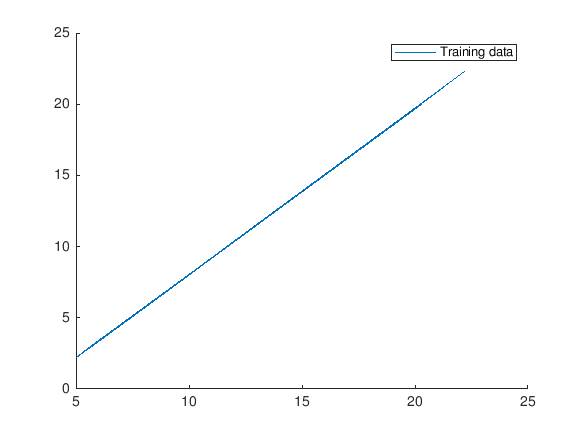

hold off % don't overlay any more plots on this figure


% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);

For population = 35,000, we predict a profit of 4519.767868


predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

For population = 70,000, we predict a profit of 45342.450129


    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

# 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

# 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

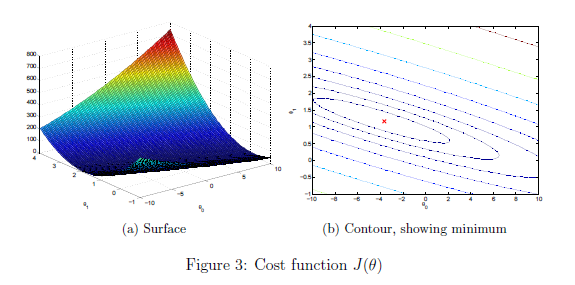

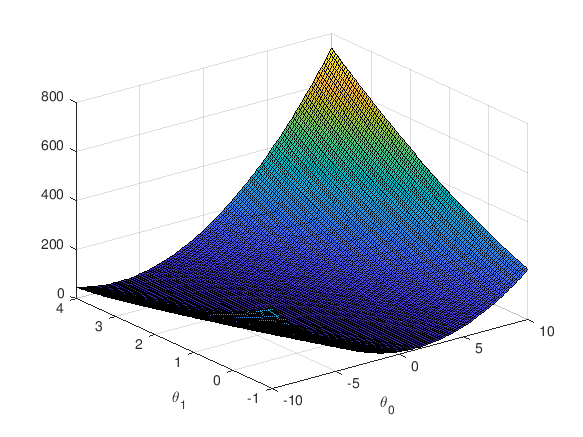

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

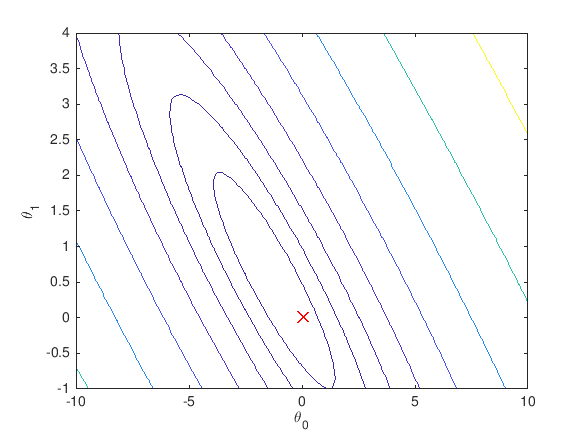


% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

# Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

# 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

 x = [2104 3], y = 399900 
 x = [1600 3], y = 329900 
 x = [2400 3], y = 369000 
 x = [1416 2], y = 232000 
 x = [3000 4], y = 539900 
 x = [1985 4], y = 299900 
 x = [1534 3], y = 314900 
 x = [1427 3], y = 198999 
 x = [1380 3], y = 212000 
 x = [1494 3], y = 242500 


The remainder of this script has been set up to help you step through this exercise.

# 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X_norm, mu, sigma] = featureNormalize(X);

mu = 	1.0e+03 *

    2.0007    0.0032


sigma =   794.7024    0.7610


**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X_norm];

# 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\text{ }\left(x^{\left(1\right)} \right)}^T -\\
{-\text{ }\left(x^{\left(2\right)} \right)}^T -\\
\vdots \text{ }\\
{-\text{ }\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \text{           }\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \text{ }\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

J_history = 	1.0e+10 *

    5.3294
         0
         0
         0
         0
         0
         0
         0
         0
         0


J_history = 	1.0e+10 *

    5.3294
    4.3427
         0
         0
         0
         0
         0
         0
         0
         0


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
         0
         0
         0
         0
         0
         0
         0


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
         0
         0
         0
         0
         0
         0


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
         0
         0
         0
         0
         0


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
         0
         0
         0
         0


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
         0
         0
         0


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
         0
         0


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
         0


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history = 	1.0e+10 *

    5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852


J_history =     5.3294
    4.3427
    3.5500
    2.9123
    2.3987
    1.9846
    1.6504
    1.3803
    1.1620
    0.9852



% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f,\n%f',theta(1),theta(2),theta(3))

Theta computed from gradient descent:
340412.659574,
110631.048958,
-6649.472950

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================

price = [1,([1650,3] - mu)./sigma] * theta; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $293081.464622

## **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

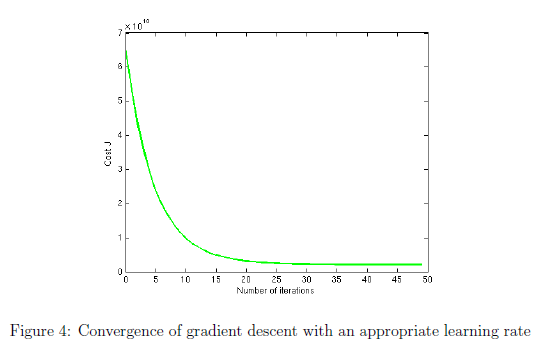

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \text{ }\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

% Run gradient descent:
% Choose some alpha value
alpha = 0.1;
num_iters = 200;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

J_history = 	1.0e+22 *

    1.3493
         0
         0
         0
         0
         0
         0
         0
         0
         0


J_history = 	1.0e+33 *

    0.0000
    2.8811
         0
         0
         0
         0
         0
         0
         0
         0


J_history = 	1.0e+44 *

    0.0000
    0.0000
    6.1518
         0
         0
         0
         0
         0
         0
         0


J_history = 	1.0e+56 *

    0.0000
    0.0000
    0.0000
    1.3135
         0
         0
         0
         0
         0
         0


J_history = 	1.0e+67 *

    0.0000
    0.0000
    0.0000
    0.0000
    2.8047
         0
         0
         0
         0
         0


J_history = 	1.0e+78 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    5.9886
         0
         0
         0
         0


J_history = 	1.0e+90 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2787
         0
         0
         0


J_history = 	1.0e+101 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    2.7303
         0
         0


J_history = 	1.0e+112 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    5.8297
         0


J_history = 	1.0e+124 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history = 	1.0e+135 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+146 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+158 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+169 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+180 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+192 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+203 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+214 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+226 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+237 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+248 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+260 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+271 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+282 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+294 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history = 	1.0e+305 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448


J_history =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.2448



% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f',theta(1),theta(2))

% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

# 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
%data = csvread('ex1data2.txt');
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta(1),theta(2),theta(3));

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

price = [theta(1) + theta(2)*1650 +theta(3)*3]; % Enter your price forumla here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f++', price);     

# Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

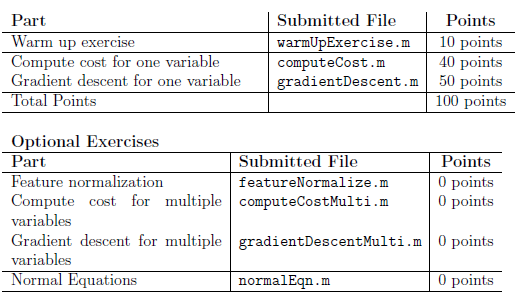

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

**Define the cleanPath function used in the environment setup section:**

Do not modify the code below.

function [] = cleanPath() 
    % cleanPath() obtains the MATLAB search path and removes any other Machine Learning exercise folders. 
    % cleanPath() also prints out the current working directory and the files contained within for reference. 
    pth = strsplit(path,pathsep); % Obtain the search path 
    pth = ([pth{contains(pth,'machine-learning-ex')},{''}]); % Obtain any ML exercise folders that have been added to the path
    rmpath(pth{:}); % Remove these folders from the path
    pwd
    dir
end